# Chapter 7, Part 4

## Amelia Rotondo, CWID: 887925113

#### Problem 19:

% Constants
g = 9.81;      
m = 80;       
c = 0.72;     
s = 0.50;      
theta0 = pi/8; 

% Set-Up for Table 
table_v0 = zeros(4, 1);
table_theta0 = zeros(4, 1);
table_rho = zeros(4, 1);
table_dist = zeros(4, 1);

Part a:

NOTE: longJumpODE is defined at the bottom of this document so it can be used throughout the code. 

% Part A - Solution:
v0 = 10; 
rho = 0.94;
Tmax = 100; 
x0 = 0; y0 = 0;

% ODE Solution
rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
opts = odeset('Events', @reachesGround);
[t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [x0, y0, theta0, v0], opts);

% Part A - Storage:
idx = 1;
table_v0(idx) = v0; 
table_theta0(idx) = rad2deg(theta0);
table_rho(idx) = rho;
table_dist(idx) = ye(:, 1);

Part b:

% Part B - Solution:
v0 = 10; 
rho = 1.29;
Tmax = 100; 
x0 = 0; y0 = 0;

% ODE Solution
rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
opts = odeset('Events', @reachesGround);
[t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [x0, y0, theta0, v0], opts);

% Part B - Storage:
idx = 2;
table_v0(idx) = v0; 
table_theta0(idx) = rad2deg(theta0);
table_rho(idx) = rho;
table_dist(idx) = ye(:, 1);

Part c:

% Part C - Solution:
rho = 0.94;
Tmax = 100; 
x0 = 0; y0 = 0;

% Solving for v0
dist = 8.9000;
v0 = fzero(@(v0) jumpDistDiff(v0, g, m, c, rho, s, theta0, Tmax, dist), 10);

% actual ODE Solution
rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
opts = odeset('Events', @reachesGround);
[t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [x0, y0, theta0, v0], opts);

% Part C - Storage:
idx = 3;
table_v0(idx) = v0; 
table_theta0(idx) = rad2deg(theta0);
table_rho(idx) = rho;
table_dist(idx) = ye(:, 1);

Part d:

% Part C - Solution:
rho = 1.29;
Tmax = 100; 
x0 = 0; y0 = 0;

% Solving for v0
dist = 8.9000;
v0 = fzero(@(v0) jumpDistDiff(v0, g, m, c, 0.94, s, theta0, Tmax, dist), 10);

% actual ODE Solution
rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
opts = odeset('Events', @reachesGround);
[t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [x0, y0, theta0, v0], opts);

% Part C - Storage:
idx = 4;
table_v0(idx) = v0; 
table_theta0(idx) = rad2deg(theta0);
table_rho(idx) = rho;
table_dist(idx) = ye(:, 1);

%  Print the Table
fprintf('  v0:    |  theta0: |   rho:  |  dist:\n');

  v0:    |  theta0: |   rho:  |  dist:


fprintf('---------------------------------------\n');

---------------------------------------


for i = 1:4
    fprintf('%.4f  | %.4f  | %.4f  | %.4f\n', table_v0(i), table_theta0(i), table_rho(i), table_dist(i));
end

10.0000  | 22.5000  | 0.9400  | 7.1331
10.0000  | 22.5000  | 1.2900  | 7.1058
11.1847  | 22.5000  | 0.9400  | 8.9000
11.1847  | 22.5000  | 1.2900  | 8.8575


Given these results, it's clear that for getting far distances, changing the jumper's initial velocity is far more important than the air density. This is easily interpreted through the difference in jump length between the four results. Since the difference between the first two shows a ~0.03 difference, and the difference between the last two shows a ~0.05 difference. However, when comparing the first and third result, the ~1.18 difference in velocity shows a ~1.77 difference. This difference is mostly-preserved when comparing the second and fourth results. **Therefore, we can conclude that the initial velocity is far more important than air density when considering jump distance. ** 

------------------------------------------------------------

#### Problem 20:

% Pendulum Parameters
g = 981; 
L = 30; 

Part a:

% Oscillation Period for Linearized Equation
T_linear = 2 * pi * sqrt(L / g);

% Display results
fprintf('Linearized Period: %.4f s\n', T_linear);

Linearized Period: 1.0988 s


Part b:

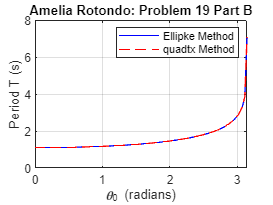

% Define the range of theta0 values
theta0 = linspace(0, 0.9999 * pi, 100);
T_ellipke = zeros(size(theta0));
T_quadtx = zeros(size(theta0));

% Tolerance for quadtx
tol = 1e-4;

% Loop over theta0 values
for i = 1:length(theta0)
    theta0_i = theta0(i);
    k_square = sin(theta0_i / 2)^2;

    % Ellipke method
    [K, ~] = ellipke(k_square);
    T_ellipke(i) = 4 * sqrt(L / g) * K;

    % quadtx method
    integrand = @(t) 1 ./ sqrt((1 - k_square .* t.^2) .* (1 - t.^2));
    K = integral(integrand, 0, 1, AbsTol = tol);
    % K = quadtx(integrand, 0, 1, tol);
    T_quadtx(i) = 4 * sqrt(L / g) * K;
end

% Plotting
figure;
plot(theta0, T_ellipke, 'b-', theta0, T_quadtx, 'r--');
xlabel('\theta_0 (radians)');
ylabel('Period T (s)');
legend('Ellipke Method', 'quadtx Method');
title('Amelia Rotondo: Problem 19 Part B');
grid on;

Part c:

% Let theta0 be small
theta0 = 0.001 

theta0 = 1.0000e-03


% Linear Solution
T_linear = 2 * pi * sqrt(L / g);

% NonLinear Solution 
k_square = sin(theta0 / 2)^2;
[K, ~] = ellipke(k_square);
T_ellipke = 4 * sqrt(L / g) * K;

% Print Solutions (they are the same)
fprintf('Linearized Period: %.4f s\n', T_linear);

Linearized Period: 1.0988 s


fprintf('NonLinear Period : %.4f s\n', T_ellipke);

NonLinear Period : 1.0988 s


Part d:

% Theta0 
theta0 = linspace(0, 0.9 * pi, 100);
omega0 = 0

omega0 = 0

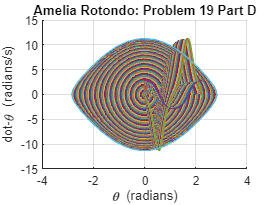


% Create figure for phase plane plots
figure;
hold on;

% Loop over theta0 values
for i = 1:length(theta0)
    theta0_i = theta0(i);
    k_square = sin(theta0_i / 2)^2;

    % Calculate the complete elliptic integral of the first kind
    [K, ~] = ellipke(k_square);

    % Calculate the period
    T = 4 * sqrt(L/g) * K;

    % Solve the ODE over one period
    initial_conditions = [theta0_i, omega0]; 
    [t, y] = ode45(@(t, y) onePenODE(t, y, g, L), [0, T], initial_conditions);

    % Plot the phase plane diagram
    plot(t, y, y(:, 1), y(:, 2));
end

% Customize the plot
xlabel('\theta (radians)');
ylabel('dot-\theta (radians/s)');
title('Amelia Rotondo: Problem 19 Part D');
grid on;
hold off;

#### Problem 22:

Part a:

Part b:

Part c:

Part d:

#### Problem 23: 

Part a:

Part b:

Part c:

Part d:

Part e:

Part f:

Part g:

Part h:

Part i:

Part j:

#### ETC-FUNCTIONS: 

Problem 19:

function dydt = longJumpODE(t, y, g, m, c, rho, s)
    % Extract State Variables 
    x = y(1);       % Horizontal position 
    y_pos = y(2);   % Vertical position
    theta = y(3);   % Angle of the jumper's velocity vector
    v = y(4);       % Magnitude of the jumper's velocity

    % Calculate the drag force
    D = (c * rho * s * v^2) / 2;

    % Compute the derivatives (RHS of the ODE system)
    dxdt = v * cos(theta);                       
    dydt = v * sin(theta);                       
    dthetadt = -g * cos(theta) / v;            
    dvdt = -(D/m) - g * sin(theta);  

    % Assemble the Vector of Derivatives
    dydt = [dxdt; dydt; dthetadt; dvdt];
end

% Event to Check for the Jump Reaching the Ground
function [value, isterminal, direction] = reachesGround(t, y)
    value = y(2);       % Check the height of the jumper, which is y(2)
    isterminal = 1;     % Stop the solver when the height crosses zero
    direction = -1;     % Detect when the height is decreasing through zero
end

% Finds Difference between Desired Distance and Distance Achieved for v0 
function distDifference = jumpDistDiff(v0, g, m, c, rho, s, theta0, Tmax, dist)

    % Solve the ODE for the v0 guess
    rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
    opts = odeset('Events', @reachesGround);
    [t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [0, 0, theta0, v0], opts);
    
    % Determine Jump Distance Difference
    jump_distance = ye(end, 1); 
    distDifference = jump_distance - dist;
end

Problem 20:

% Creates the Single-Pendulum ODE 
function dydt = onePenODE(t, y, g, L)
    % Extract state variables
    theta = y(1); % Angular position
    omega = y(2); % Angular velocity
    
    % Compute the derivatives (RHS of the ODE system)
    dthetadt = omega;
    domegadt = -(g/L) * sin(theta);
    
    % Assemble the vector of derivatives
    dydt = [dthetadt; domegadt];
end

% Event function to stop integration when theta crosses zero
function [value, isterminal, direction] = eventFunction(t, y)
    value = y(1);      % Detect theta = 0
    isterminal = 1;    % Stop the integration
    direction = 0;     % Detect all zero crossings
end